clear
close all
clc

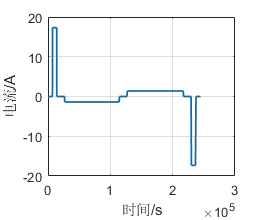

load('Data.mat');
painting_singleCurve(Time,I,'blue','thick','时间/s','电流/A',-1);
ylim([-20,20]);

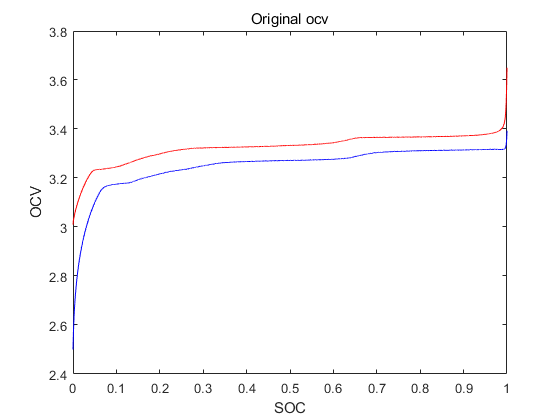

k = 1; 
for index = 1:length(I)-1      % 找出充放电最后一时刻
    if (abs(I(index)) > 0.01 && abs(I(index+1)) < 0.01 )
        endIndex(k) = index;         % 记录切换索引 [放电至55% 充电5%...充电5% 放电5%...放电5% 放空... 
        k = k+1;                     %              充至50% 放电5%...放电5% 充电5%...充电5% 充满]
    end
end

k = 1; 
for index = 2:length(I)      % 找出充放电开始一时刻
    if (abs(I(index)) > 0.01 && abs(I(index-1)) < 0.01 )
        startIndex(k) = index;         % 记录切换索引 [静置 充电5%前...充电5%前 放电5%前...放电5%前 放空前... 
        k = k+1;                     %              充至50%前 放电5%前...放电5%前 充电5%前...充电5%前 充满前]
    end
end


ocvCharge = Ut(startIndex(2)-1:endIndex(2)); % -1 为了补充SOC 0位
ocvDischarge = Ut(startIndex(3)-1:endIndex(3)); % -1 为了补充SOC 1位

socCharge = Capacity(startIndex(2)-1:endIndex(2))/Capacity(endIndex(2));
socDischarge = 1-Capacity(startIndex(3)-1:endIndex(3))/Capacity(endIndex(3));

figure,plot(socCharge,ocvCharge,'r'),hold on, plot(socDischarge,ocvDischarge,'b');
title('Original ocv');
xlabel('SOC'),ylabel('OCV');

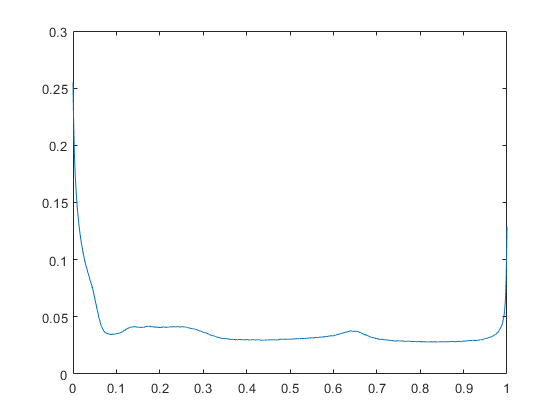

for i = 1:1:1000 % 获取0.001分辨率OCV-SOC在充放电下的结果
    socTable1000(i) = i/1000;
    ocvCharge1000(i) = interp1(socCharge,ocvCharge,i/1000); 
    ocvDisharge1000(i) = interp1(socDischarge,ocvDischarge,i/1000);
end

socTable1000 = [0 , socTable1000]; % 补充 SOC 0 位置
ocvCharge1000 = [ocvCharge(1) , ocvCharge1000]; % 补充 SOC 0 位置
ocvDisharge1000 = [ocvDischarge(end) ,ocvDisharge1000]; % 补充 SOC 0 位置

Hocv = (ocvCharge1000 - ocvDisharge1000)/2; % 数值比静置获取的迟滞参数大很多
figure, plot(socTable1000, Hocv);

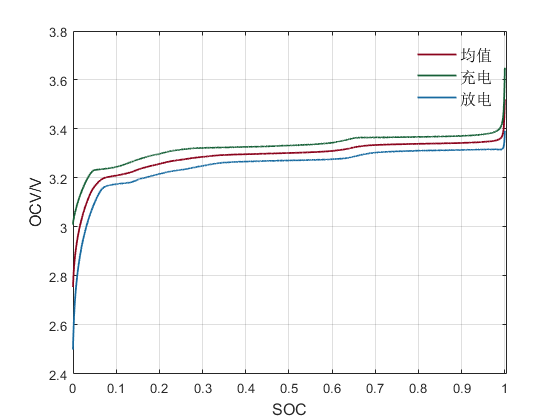


ocvAverage1000 = (ocvCharge1000+ocvDisharge1000)/2; % 务必/2 保持统一即可
figure, plot(socTable1000,ocvAverage1000,'color',[140,3,28]/256,'LineWidth',1.3)
hold on, 
plot(socCharge,ocvCharge,'color',[22,96,55]/256,'LineWidth',1.3)
hold on, plot(socDischarge,ocvDischarge,'color',[23,106,161]/256,'LineWidth',1.3);
xlabel('\fontsize {12}SOC'),ylabel('\fontsize {12}OCV/V');
legend('\fontsize {12}均值','\fontsize {12}充电','\fontsize {12}放电');
legend boxoff;
xlim([0,1.005]);
grid on